# HomeWork n.2 2021/22

***  Mazza Lorenzo 0124002003***

%Come richiesto, per prima cosa imposto tutti i numeri in formato long (15 cifre dopo la virgola)
format long

1.**  Interpolazione**

**Definire un dominio **$[a,b]$** ed una funzione composta **$f(x)$** in MATLAB combinando  le principali funzioni elementari (polinomi, funzioni trigonometriche, logaritmi, esponenziali, etc.). Per stabilire un intervallo nel quale **$f$**sia definita e non prensenti punti di discontinuità, utilizzare eventualmente la function MATLAB *****ezplot *****per osservarne il grafico.**

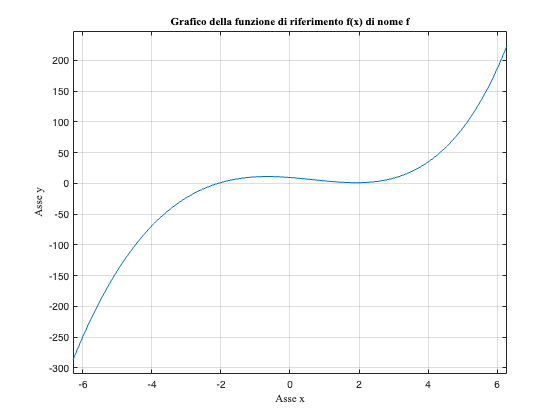

%creo la mia funzione di riferimento
f= @(x) x.^3 - 2.*x.^2 - 5.*x + 6 + cos(x) + log(5) + 2.^x; %Si inserisce il "punto" prima degli operatori *, /, ^, \ quando si vuole che gli operatori stessi effettuino l'operazione relativa su vettori o matrici, elemento per elemento.
figure(1) %uso figure specificando ogni volta il numero della figura creata
ezplot(f) %con il comando ezplot visualizzo la mia funzione su grafico 
hold on %hold on mi permette di conservare i grafici negli assi correnti (i nuovi grafici non eliminano quelli già esistenti)
grid on %grid on ci fa visualizzare la griglia 
xlabel("Asse x",'FontName','Times New Roman') %do un nome all'asse x
ylabel("Asse y",'FontName','Times New Roman') %do un nome all'asse y
title("Grafico della funzione di riferimento f(x) di nome f",'FontName','Times New Roman') %do un titolo al mio grafico
hold off
grid on

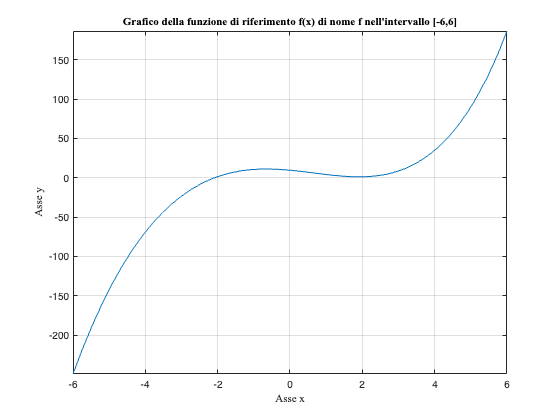

figure(2)
%scelgo il mio intervallo [ar-br]
ar=-6; 
br=6;
fplot(f,[ar,br]) %plotto la funzione nell'intervallo [ar-br]
grid on
xlabel("Asse x",'FontName','Times New Roman') %do un nome all'asse x
ylabel("Asse y",'FontName','Times New Roman') %do un nome all'asse y
title("Grafico della funzione di riferimento f(x) di nome f nell'intervallo [-6,6]",'FontName','Times New Roman')

**Definire quindi un insieme di **$m$** punti **$P=\{(x_i,y_i)\}_{i=1}^m$** con **$11 \leq m \leq 21, m \in \mathbb{N}$**. Le ascisse di **$P$** sono linearmente distribuite in **$[a,b]$**, le ordinate sono i corrispondenti valori assunti dalla valutazione di **$f(x)$**.**

Scelgo m = 15.

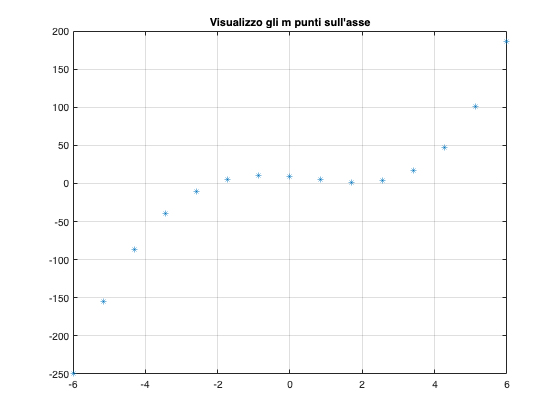

figure(3)
m=15; %scelgo l'insieme di punti m
%distribuisco gli m punti
x=linspace(ar,br,m)';  
y=f(x); %assegno la funzione di riferimento in x ad y
plot(x,y,'*') %con plot visualizzo i punti generati e scelgo l'asterisco per identificarli
grid on %metto la griglia
title("Visualizzo gli m punti sull'asse" ) %do un titolo al grafico

         ** 1.1. Definire un insieme **$\mathcal{F}$**di funzioni modello polinomiali. Scegliere un'opportuna base così da determinare il polinomio **$p$  $\in$ $\mathcal{F}$** che interpola **$f$** nei nodi **$x_i$**. Costruire e risolvere il relativo sistema lineare **$Ba=y$** (non usare il comando backslash di MATLAB).  Calcolare inoltre l'indice di condizionamento della matrice **$B$**.**

B = [ones(size(x)) x x.^2 x.^3 x.^4 x.^5 x.^6 x.^7 x.^8 x.^9 x.^10 x.^11 x.^12 x.^13 x.^14] %creo la matrice a partire da x fino ad arrivare ad x^14, ovvero fino ad m-1

B = 1.0e+10 *

   0.000000000100000  -0.000000000600000   0.000000003600000  -0.000000021600000   0.000000129600000  -0.000000777600000   0.000004665600000  -0.000027993600000   0.000167961600000  -0.001007769600000   0.006046617600000  -0.036279705600000   0.217678233600000  -1.306069401600000   7.836416409600000
   0.000000000100000  -0.000000000514286   0.000000002644898  -0.000000013602332   0.000000069954852  -0.000000359767811   0.000001850234457  -0.000009515491492   0.000048936813386  -0.000251675040272   0.001294328778541  -0.006656548003926   0.034233675448764  -0.176058902307928   0.905445783297914
   0.000000000100000  -0.000000000428571   0.000000001836735  -0.000000007871720   0.000000033735943  -0.000000144582614   0.000000619639776  -0.000002655599040   0.000011381138742  -0.000048776308894   0.000209041323829  -0.000895891387840   0.003839534519316  -0.016455147939924   0.070522062599673
   0.000000000100000  -0.000000000342857   0.000000001175510  -0.000000004030321  

%come notiamo, si tratta di una matrice di Van Der Monde

rank(B) %Controllo il rango che mi permette di sapere se la matrice è non singolare. Una matrice quadrata B è non singolare se il suo determinante det(B) è diverso da zero.

ans =     15


if det(B)~=0 %mi permette di verificare se il determinante è uguale o diverso da 0
    fprintf("Determinante diverso da 0")
else
    fprintf("Determinante uguale a 0")
end

Determinante diverso da 0

cond(B) %indice di condizionamento della matrice B

ans =      3.641339814682231e+11


a = Sgauss_pivot(B,y) %Faccio uso della funzione Sgauss_pivot, ovvero il metodo di Gauss con pivoting parziale, per calcolarmi il coefficiete della matrice per costruire la funzione interpolante. In pratica vado a risolvere il sistema lineare.

a =    9.609437912434174
  -4.306852808417465
  -2.259773392352623
   1.055504086002118
   0.051284588236341
   0.001333368069242
  -0.001234740570652
   0.000015250045971
   0.000026098001222
   0.000000102061667


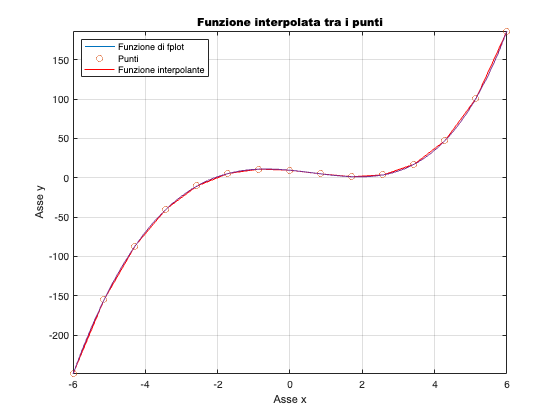

figure(4)
fplot(f,[ar,br]) %plotto funzione f in intervallo [ar-br]
hold on %conservo il grafico
grid on %metto la griglia
x_inter = linspace(ar,br, m); %distribuisco di nuovo gli m punti nel determinato intervallo
y_inter = polyval(a(end:-1:1),x_inter); %valuto il polinomio in ogni punto m in [ar-br] passando come argomenti sia il risultato di Sgauss_pivot che il risultato della linspace
plot(x,y,'o',x_inter,y_inter,'r') %vado a visualizzare sia i punti, sia la funzione interpolante questi ultimi
fplot(f,[ar,br]) %plotto la funzione f in [ar-br]

title('Funzione interpolata tra i punti', 'FontName','Arial Black') %do un titolo al grafico
xlabel("Asse x",'FontName','Arial') %do un nome all'asse x
ylabel("Asse y",'FontName','Arial') %do un nome all'asse y
legend('Funzione di fplot', 'Punti','Funzione interpolante', 'Location','northwest') %creo la legenda

hold off

       ** 1.2. Valutare il polinomio **$p$** su una griglia di **$N$** punti di valutazione distribuiti casualmente in **$[a,b]$**. Fissare **$N\,\,( 201 \leq N \leq 399)$**. Calcolare l'errore di interpolazione della funzione interpolante scelta al punto precedente.**

Ora vado a valutare con la griglia di valutazione:

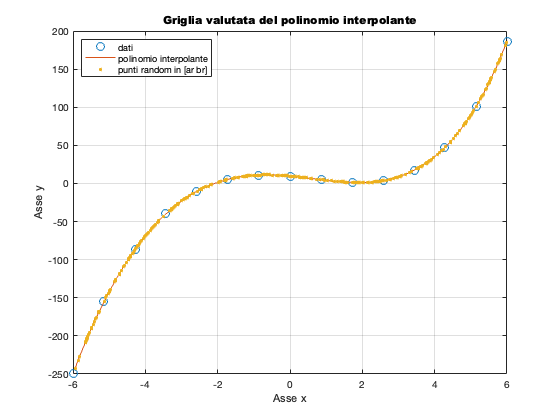

figure(5)
n_rand=369; %scelgo il numero di punti da distribuire casualmente in [ar-br]
xx = ar+(br-ar)*rand(n_rand,1); %distribuisco i punti di valutazione all'interno del mio intervallo [ar-br]
xx = sort(xx)'; %effettuo la trasposizione dei punti
BB = [ones(size(xx)) xx xx.^2 xx.^3 xx.^4 xx.^5 xx.^6 xx.^7 xx.^8 xx.^9 xx.^10 xx.^11 xx.^12 xx.^13 xx.^14];
yy = polyval(a(end:-1:1),xx); %valuto il polinomio in ogni punto randomico

plot(x,y,'o', xx, yy,'MarkerSize',8)   %riprendo il grafico di prima
hold on
plot(xx, yy, '*','MarkerSize',1.5) %valutazione del polinomio
title('Griglia valutata del polinomio interpolante', 'FontName','Arial Black')
legend('dati','polinomio interpolante','punti random in [ar br]', 'Location','northwest')
xlabel("Asse x",'FontName','Arial')
ylabel("Asse y",'FontName','Arial')
hold on
grid on

Calcolo ora l'errore di interpolazione della funzione interpolante scelta al punto precedente:

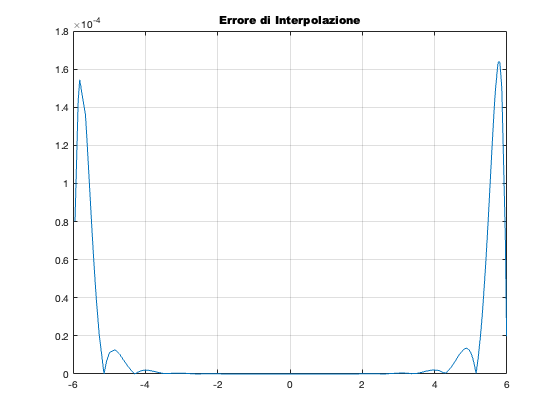

err_inter = abs(yy-f(xx)); %calcolo l'errore di interpolazione
figure(6)
plot(xx, err_inter) %andamento dell'errore
title('Errore di Interpolazione', 'FontName','Arial Black')
grid on

Un altro metodo è il seguente:

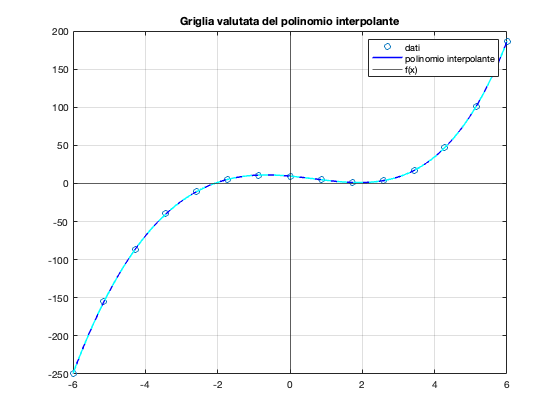

figure(7)
plot(x,y,'o');
hold on
coeff = polyfit(x,y, length(x)-1);   
ascisse_valutazioni = linspace(ar,br,369);%griglia di valutazione di 250 punti equispaziati su [ar,br]
valori_pol = polyval(coeff,ascisse_valutazioni); % valutazione del polinomio sulla griglia di punti

plot(ascisse_valutazioni, valori_pol,'b','LineWidth',1.5)
xline(0); yline(0);
title('Griglia valutata del polinomio interpolante')
hold on
grid on
plot(ascisse_valutazioni, f(ascisse_valutazioni),'--','LineW',1.5, 'color', 'c')
legend('dati','polinomio interpolante','f(x)')

Andiamo a valutare l'errore:

err_int=abs(valori_pol-f(ascisse_valutazioni))

err_int = 1.0e-03 *

   0.000000000085265   0.051529591843291   0.090351669257416   0.118506357495107   0.137779202390220   0.149727266745003   0.155702981459171   0.156875913944532   0.154252607984517   0.148694637715607   0.140935011472720   0.131593051548862   0.121187867733852   0.110150535078901   0.098835079995752   0.087528369988377   0.076458997824602   0.065805243309569   0.055702191076534   0.046248077438804   0.037509932212743   0.029528580114402   0.022323058288976   0.015894504713287   0.010229566413500   0.005303373995957   0.001082125208995   0.002474684293929   0.005412346098410   0.007779307622968   0.009625792927181   0.011002649443981   0.011960393777599   0.012548433375059   0.012814444602327   0.012803885482526   0.012559627990072   0.012121692051892   0.011527068735973   0.010809618558483   0.010000033626056   0.009125853750902   0.008211526690616   0.007278504412511   0.006345368547045   0.005427977868067   0.004539632911360   0.003691252388194   0.00289155693167

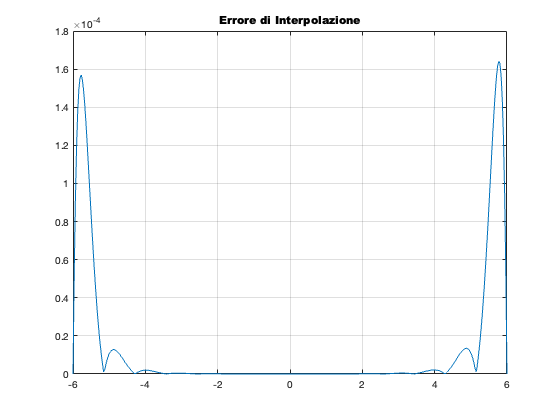

figure(8)
plot(ascisse_valutazioni, err_int)
title('Errore di Interpolazione', 'FontName','Arial Black')

grid on

**1.3. Interpolare i punti **$P$** mediante una spline **$s$** di terzo grado di tipo *****not-a-knot*****.  Valutare l'interpolante ottenuto sulla una griglia di **$N$** punti di valutazione.**

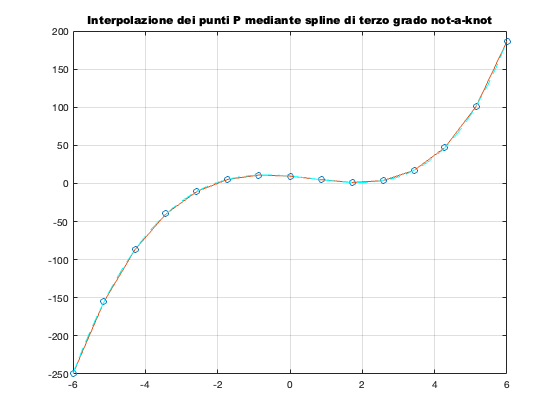

figure(9)
xx_spline = linspace(ar, br, m); %griglia spline su m punti
yy_spline = spline(x, y, xx_spline);%valori spline
plot(x, y, 'o', xx_spline, yy_spline)
title('Interpolazione dei punti P mediante spline di terzo grado not-a-knot', 'FontName','Arial Black')

hold on
grid on
fplot(f, [ar, br],'--c')

Valuto l'interpolante ottenuto su una griglia di N punti di valutazione:

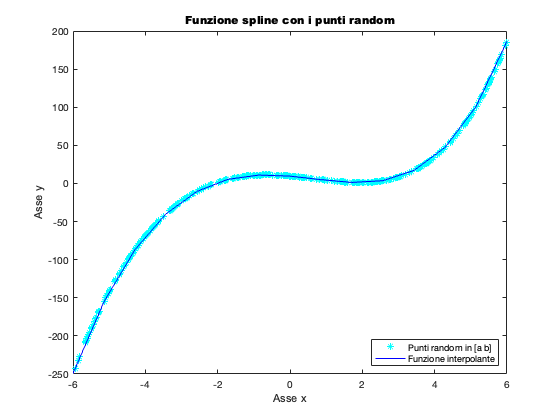

figure(10)
xs_spline = spline(x,y);
ys_spline = ppval(xs_spline, xx_spline);

plot(xx,f(xx),'c*',xx_spline,ys_spline,'b-')
title('Funzione spline con i punti random','FontName','Arial Black')
xlabel("Asse x",'FontName','Arial')
ylabel("Asse y",'FontName','Arial')
legend('Punti random in [a b]','Funzione interpolante', 'Location','southeast')

**        1.4. Fissare un valore **$n\,\,( 10 \leq n \leq 19)$** e definire un nuovo insieme di punti **$Q = \{(x_j, y_j)\}_{j=1}^n$** le cui ascisse sono i nodi di Chebyshev in **$[a,b]$** e le cui ordinate sono i valori corrispondenti assunti da **$f(x)$**. Costruire il polinomio interpolante i punti **$Q$** e valutarlo sulla griglia di valutazione generata al punto 1.2.**

Vado a calcolare e visualizzare la valutazione della funzione sui nodi di Chebyshev:

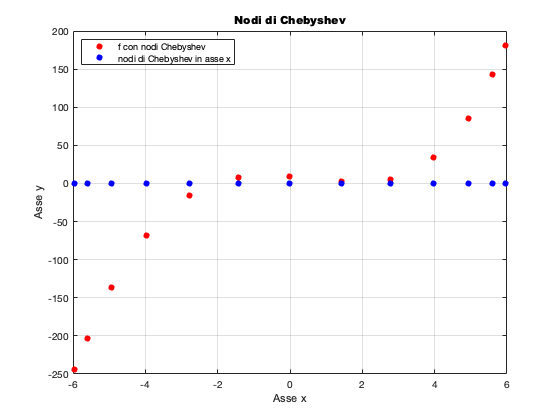

n_cheb = 13; % numero dei nodi 
nodicheb=AscisseCheb1(ar,br,n_cheb)';
nodicheb = nodicheb(end:-1:1);
valori = f(nodicheb);% valori della funzione di Runge sugli n nodi di Chebyshev
figure(11)
%mostro il grafico con gli f nodi di Chebyshev e i nodi di Chebyshev sull'asse delle x
plot(nodicheb,valori,'.r','MarkerSize',22) %visualizzo i nodi di Chebyshev
hold on %conservo il grafico
grid on %metto la griglia
plot(nodicheb,0,'.b','MarkerSize',22) %proiezione sull'asse delle x
title('Nodi di Chebyshev','FontName','Arial Black')
xlabel("Asse x",'FontName','Arial')
ylabel("Asse y",'FontName','Arial')
legend('f con nodi Chebyshev','nodi di Chebyshev in asse x','Location','northwest')

Come notiamo, agli estremi la densità è maggiore

%costruzione del polinomio interpolante (Matrice di Van Der Monde)
B1=[ones(size(nodicheb)) nodicheb nodicheb.^2 nodicheb.^3 nodicheb.^4 nodicheb.^5 nodicheb.^6 nodicheb.^7 nodicheb.^8 nodicheb.^9 nodicheb.^10 nodicheb.^11 nodicheb.^12 nodicheb.^13 nodicheb.^14]

B1 = 1.0e+10 *

   0.000000000100000   0.000000000595625   0.000000003547695   0.000000021130971   0.000000125861417   0.000000749662476   0.000004465179553   0.000026595740200   0.000158410963861   0.000943535817476   0.005619938274226   0.033473775580247   0.199378284408468   1.187547553408389   7.073333968091643
   0.000000000100000   0.000000000561010   0.000000003147319   0.000000017656768   0.000000099056191   0.000000555714883   0.000003117614654   0.000017490122040   0.000098121289163   0.000550469994725   0.003088190317072   0.017325048641794   0.097195211312355   0.545274607729761   3.059043689707467
   0.000000000100000   0.000000000493790   0.000000002438289   0.000000012040034   0.000000059452523   0.000000293570801   0.000001449624197   0.000007158103954   0.000035346024387   0.000174535246766   0.000861838152710   0.004255673368151   0.021014103123009   0.103765606958772   0.512384522170391
   0.000000000100000   0.000000000397874   0.000000001583034   0.000000006298474 

rank(B1) %mi permette di sapere se la matrice è non singolare

ans =     13


if det(B)~=0 %mi permette di verificare se il determinante è uguale o diverso da 0
    fprintf("Determinante diverso da 0")
else
    fprintf("Determinante uguale a 0")
end

Determinante diverso da 0

cond(B1) %calcolo l'indice di condizionamento della matrice

ans =      1.162131940210790e+11


a_cheb = Sgauss_pivot(B1, valori) %Risoluzione del sistema lineare

a_cheb =    9.609437912434117
  -4.306865160076186
  -2.259725614198979
   1.055513680340178
   0.051247330397328
   0.001331243506838
  -0.001226401443870
   0.000015451309784
   0.000025295279019
   0.000000092806395


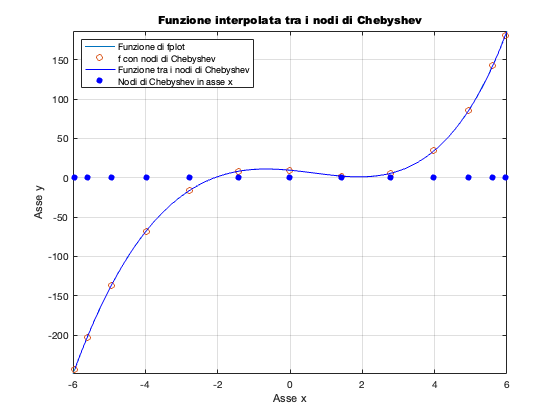

figure(12)
fplot(f, [ar, br]); %mi prendo il grafico del punto di prima
hold on
y_cheb = polyval(a_cheb(end:-1:1),xx);
plot(nodicheb,valori,'o', xx, y_cheb, 'b') %Visualizzo i nodi e l'interpolazione
hold on
grid on
plot(nodicheb,0,'.b','MarkerSize',22)

title('Funzione interpolata tra i nodi di Chebyshev', 'FontName','Arial Black')
xlabel("Asse x",'FontName','Arial')
ylabel("Asse y",'FontName','Arial') 
legend('Funzione di fplot', 'f con nodi di Chebyshev','Funzione tra i nodi di Chebyshev','Nodi di Chebyshev in asse x', 'Location','northwest')
hold off

** 1.5. Infine, mostrare graficamente l'andamento dell'errore di interpolazione. Confrontare numericamente l'errore con quello ottenuto al punto 1.2**

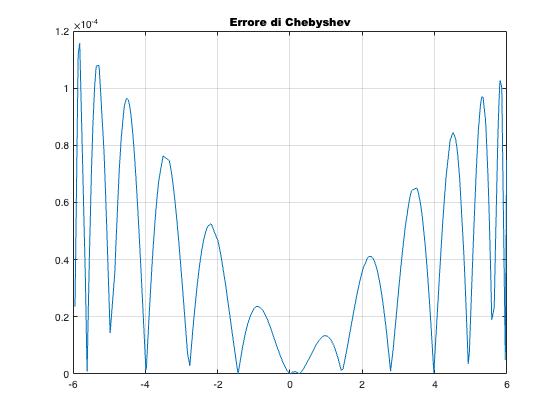

err_cheb = abs(y_cheb - f(xx)); %errore di interpolazione

figure(13)
plot(xx, err_cheb)
grid on
title("Errore di Chebyshev", 'FontName','Arial Black')

Vado a confrontare l'errore con l'errore risultato nel punto 1.2:

err_totdiff = abs(err_cheb - err_inter) %controllo effettuato punto per punto sul confronto con i valori del punto 1.2

err_totdiff = 1.0e-03 *

   0.056596520352059   0.031420218704170   0.038497950811234   0.038764723257145   0.103477090220849   0.106240327511387   0.112716672134638   0.118725682540344   0.120313405034267   0.097837224672048   0.082726456270166   0.059298810100472   0.010209664736749   0.004623138920579   0.022432767877945   0.046957210997789   0.063485134148777   0.069129632038312   0.085162543484785   0.085410142304454   0.086352625174868   0.077902993211865   0.054554579833166   0.053948884271904   0.042002587719026   0.026052883413286   0.013535878764515   0.011678589373787   0.008447781766563   0.002822174394623   0.022924097777377   0.024088047609894   0.025774776304388   0.027476912720203   0.032278413328868   0.059529175416628   0.060896784077613   0.061234512529040   0.073315501467164   0.073519340190842   0.085601327768359   0.087683910990677   0.091322273092942   0.092091068722766   0.091936361499734   0.091241596649638   0.089893375999850   0.088840709679516   0.0855105801

** 1.6. Considerare il poligono di **$N$**vertici costituito dai valori della curva parametrica interpolata al punto (1.2) e, tramite il comando **`fill, `**visualizzare in una figura tale poligono colorato con un colore generato da una terna RGB.**

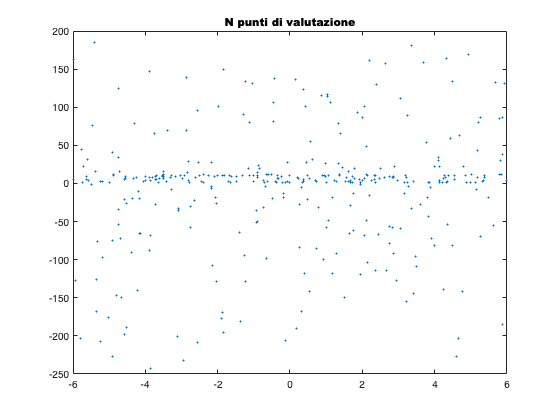

%COSTRUZIONE POLIGONO AVENTE N VERTICI
xy = sort((br-ar)*rand(1,n_rand)+ar); 
yx=zeros(369);
yx=yy;
yx=yx(randperm(n_rand));
plot(xy,yx,'.')
title('N punti di valutazione', 'FontName','Arial Black')

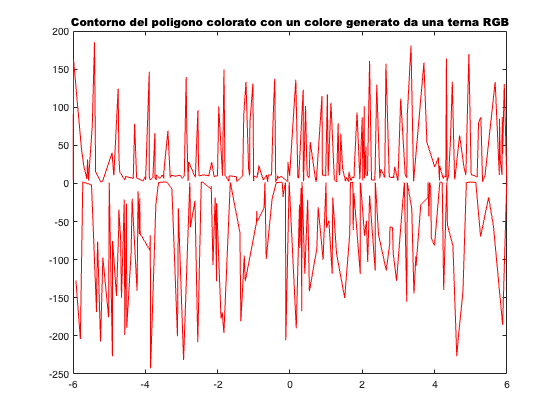

%CONTEGGIO DEI PUNTI CHE SI TROVANO AL DI SOTTO E AL DI SOPRA DELLA SOGLIA
%IMPOSTATA A 2(linea immaginaria)
down=0;up=0;
for i=1:n_rand
    if yx(i)<2
        down=down+1;
    else
        up=up+1;
    end
end

%VADO A CREARE I VETTORI LE CUI COMPONENTI SARANNO LE ASCISSE E LE ORDINATE
%NELL'ORDINE CORRETTO
sottox=zeros(1,down);
sottoy=zeros(1,down);
soprax=zeros(1,up);
sopray=zeros(1,up);

%VADO A SCORRERE OGNI SINGOLO PUNTO. 
%SE UN PUNTO SI TROVA AL DI SOTTO DI 2, VIENE INSERITO NEL VETTORE 'SOTTO',
%MENTRE,SE SI TROVA AL DI SOPRA, VIENE INSERITO NEL VETTORE 'SOPRA'
%PARTENDO DALLA FINE
j=1;
k=1;
for i=1:n_rand
    if yx(i)<2
        sottoy(j)=yx(i);
        sottox(j)=xy(i);
        j=j+1;
    else
        var=up-k+1;
        sopray(var)=yx(i);
        soprax(var)=xy(i);
        k=k+1;
    end
end

%EFFETTUO LA CONCATENAZIONE DEGLI ARRAY PER OTTENERNE UNO NUOVO CHE
%COMPRENDE TUTTI I PUNTI ORDINATI NEL MODO CORRETTO
xtot=cat(2,sottox,soprax);
ytot=cat(2,sottoy,sopray);
xtot1=zeros(length(xtot)+1);
ytot1=zeros(length(ytot)+1);
xtot1=xtot;
ytot1=ytot;

%EFFETTUO LA CHIUSURA DEL POLIGONO (L'ULTIMO PUNTO AL DI SOPRA DELLA SOGLIA
%VIENE UNITO ALL'ULTIMO PUNTO AL DI SOTTO DELLA SOGLIA. LA STESSA COSA
%AVVIENE CON IL PRIMO PUNTO AL DI SOPRA E AL DI SOTTO DELLA SOGLIA.
xtot1(n_rand+1)=xtot(1);
ytot1(n_rand+1)=ytot(1);

%MOSTRO I GRAFICI LASCIANDO DELLO SPAZIO PER VISUALIZZARE MEGLIO IL TUTTO
xmin=min(xtot)-1;
xmax=max(xtot)+1;
ymin=min(ytot)-1;
ymax=max(ytot)+1;

plot(xtot,ytot,'r')
title('Contorno del poligono colorato con un colore generato da una terna RGB', 'FontName','Arial Black')

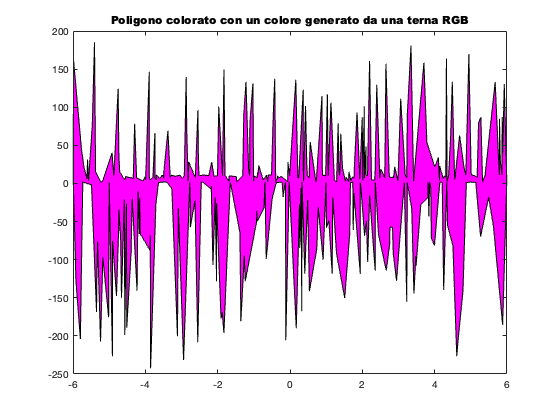

fill(xtot1,ytot1,[1 0 1])
title('Poligono colorato con un colore generato da una terna RGB', 'FontName','Arial Black')

**PUNTO 2:**

**Si considerino le seguenti curve parametriche:**

**         1. **$x = 4\sin\Big(\frac{1}{4}t\Big)\quad\quad y = 1 - 2\cos^2\Big(\frac{1}{4}t\Big)\quad\quad -52\pi \leq t \leq 34\pi$

**         2. **$x = 2e^t\quad\quad y = \cos(1+e^{3t})\quad\quad  0 \leq t \leq \frac{3}{4}$

**         3. **$x = t\cos(t)\quad\quad y = t\sin(t)\quad\quad -2\pi \leq t \leq 2\pi$

**         4. **$x = \cos t
 + \frac{1}{4}\cos(8t)\quad\quad y = \sin t + \frac{1}{4}\sin(8t)\quad\quad 0\leq t \leq 2\pi$

**Scegliere una di tali curve e campionarla in **$n$** punti **$P=\{(x_i,y_i)\}_{i=1}^n$**, corrispondenti a **$n$** punti **$t_i$** equispaziati nell'intervallo **$[a,b]$** in cui varia il parametro **$t$** (fissare **$20<n<30$**):**

**2.1. / 2.2. **

**Costruire due spline parametriche **$p_x$** e **$p_y$** che interpolino rispettivamente i punti **$(t_i,x_i)$** e i punti **$(t_i, y_i)$**  (**$i = 1,\ldots, n$**);**

**Valutare le spline parametriche su una griglia fitta opportuna e mostrare il grafico della curva parametrica interpolata:**

Scelgo la curva parametrica n.2 : 


$$x = 2e^t\quad\quad y = \cos(1+e^{3t})\quad\quad  0 \leq t \leq \frac{3}{4}$$


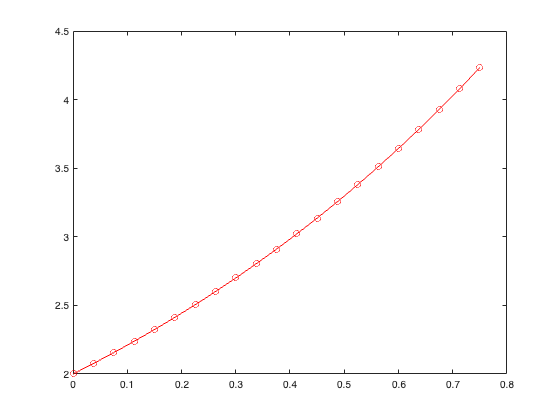

figure(14)

n = 21; 
t = linspace(0,3/4,n); %punti equispaziati nell'intervallo richiesto 
tt = linspace(t(1),t(end),500); %creo la griglia dei punti distribuendo i punti nell'intervallo

for i=1:n %campionamento della curva scelta
    x(i) = 2.*exp(t(i)); %x della curva scelta
    y(i) = cos(1+exp(3.*t(i))); %y della curva scelta
end

xsplineC = spline(t,x,tt); %spline con la funzione x

plot(t,x,'ro',tt,xsplineC,'r')

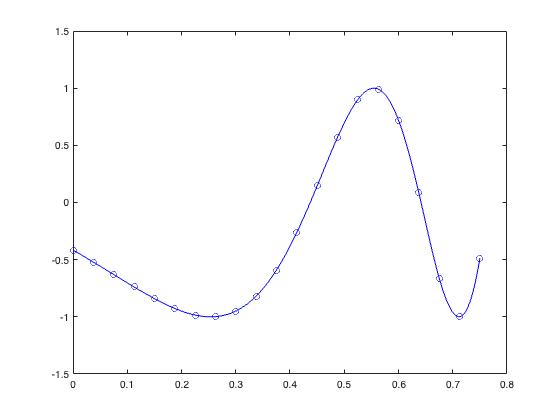

figure(15)
ysplineC = spline(t,y,tt); %spline y nell'intervallo scelto                  
plot(t,y,'bo',tt,ysplineC,'b')

**2.3/2.4/2.5.  Ripetere i punti (2.1) e (2.2) su un insieme di **$m=40$** punti **$S = \{(x_j,y_j)\}_{j=1}^m$** le cui ascisse ed ordinate sono valori ottenuti dall'utilizzo del comando **`ginput`** usato su una immagine a propria scelta oppurtunamente caricata (usare **`imread). `**Le coordinate devono essere estese aggiungendo in coda un punto fittizio uguale al primo punto, in modo tale che **`x`** e **`y`** siano i vettori delle coordinate dei vertici di un poligono (chiuso). ** **Calcolare il perimetro del poligono ottenuto al punto precedente tramite un'opportuna function che sarà allegata in fondo al file **`.mlx. `**Ricostruire inoltre la curva parametrica passante per i punti definiti al punto (2.3) mediante le cubiche di Hermite (non spline cubiche). Calcolare la norma infinito del vettore contenente le ordinate assunte dalla valutazione della cubica di Hermite:**

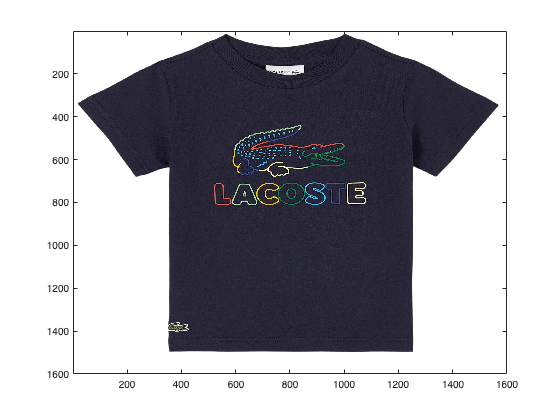

%PERMETTO DI CARICARE L'IMMAGINE E LA TABELLA DEL PUNTO 3 TRAMITE LOAD
%ATTENZIONE: SE IL LOAD FALLISCE CAMBIARE IL PERCORSO INSERENDO QUELLO
%CONTENENTE L'IMMAGINE ALLEGATA E LA TABELLA DURANTE L'INVIO DEL PROGETTO CON ESTENSIONE
%.mat
load /Users/lorenzomazza/Desktop/Istruzione-Lavoro/UniversitàInformatica/MegaAppunti/CalcoloNumerico/HW2_Mazza_Lorenzo/DatiHW2.mat
image(A)

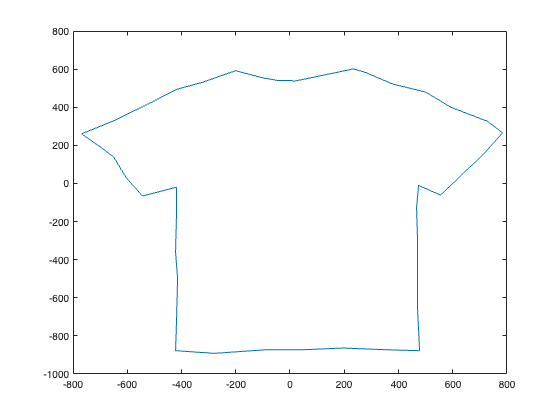

%Centralizzazione dell'immagine
xc=mean(xi);
yc=mean(yi);
xi = xi-xc;
yi = (yi-yc);
%Generazione punti fittizi (chiusura della figura)
xi= [xi;xi(1)];
yi= [yi;yi(1)];
figure(16)
plot(xi,yi,0,0)

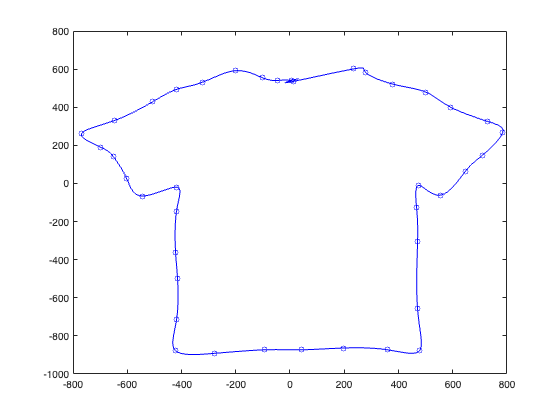

figure(17)
g = 1:length(xi);
gg = linspace(g(1),g(end),500); %distribuzione punti scelti

%spline x ed y dei punti scelti
xispline = spline(g,xi',gg);  
yispline = spline(g,yi',gg); 

%matrice delle coordinate generate dai punti
miafotoS=[xispline;yispline];
plot(xi,yi,'bo',miafotoS(1,:),miafotoS(2,:),'b','markersize',5)

perimetro(xi,yi)

perimetro_poligono =      5.425147523756716e+03


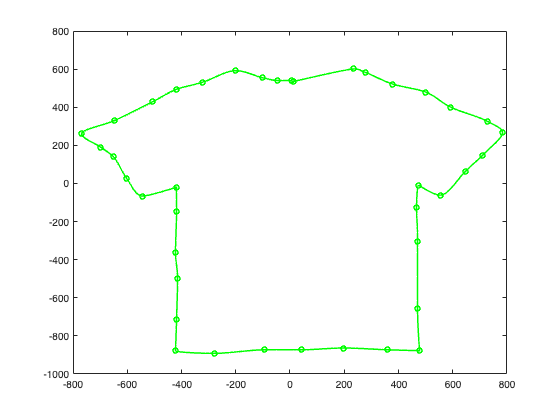

figure(18)
xcubHermN = pchip(g,xi,gg);             
ycubHermN = pchip(g,yi,gg);  
plot(xi,yi,'go',xcubHermN,ycubHermN,'g','markersize',5,'linewidth',1.5)

norm(ycubHermN,Inf)

ans =      8.916382517897106e+02


**3. Approssimazione**

**Scaricare il dataset dell'andamento del covid da **[**https://github.com/pcm-dpc/COVID-19**](https://github.com/pcm-dpc/COVID-19)

**Caricare il dataset in matlab utilizzando il comando **`readtable`**.**

%ATTENZIONE: Data è contenuto in DatiHW2**.
Data 

Data = 837×24 table
           data             stato     ricoverati_con_sintomi    terapia_intensiva    totale_ospedalizzati    isolamento_domiciliare    totale_positivi    variazione_totale_positivi    nuovi_positivi    dimessi_guariti    deceduti    casi_da_sospetto_diagnostico    casi_da_screening    totale_casi    tamponi    casi_testati         note         ingressi_terapia_intensiva    note_test    note_casi    totale_positivi_test_molecolare    totale_positivi_test_antigenico_rapido    tamponi_test_molecolare    tamponi_test_antigenico_rapido
    ___________________

**Generare un insieme di punti **$C=\{(t_i,y_i)\}_{i=1}^n$** le cui ascisse il tempo **$t_1,t_2,\ldots,t_n$**. I valori sono estratti dalla tabella precedentemente caricata. Scegliere una colonna a piacere che descrive un attributo della tabella. Scegliere inoltre **$5 \leq n \leq 11$**.**

num_rcs = 7; %scelgo un numero tra 5 e 11

ricoverati_con_sintomi = Data.ricoverati_con_sintomi %estrapolo i dati dalla colonna scelta e li assegno alla variabile creata

ricoverati_con_sintomi =          101
         114
         128
         248
         345
         401
         639
         742
        1034
        1346


**         3.1 Costruire e valutare, su una griglia fitta di almeno 100 punti, utilizzando i metodi studiati, la retta dei minimi quadrati approssimante i dati.**

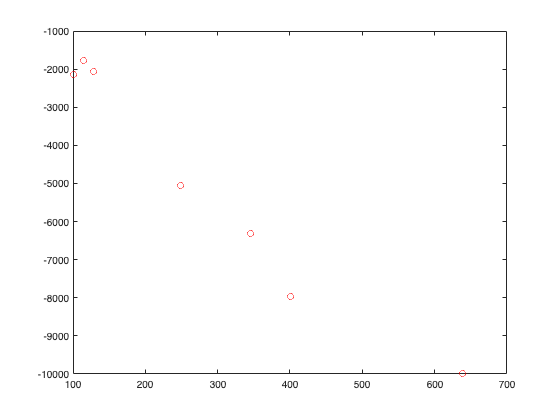

figure (19)
rcs = 1:length(num_rcs); %lunghezza della colonna
for i=1:num_rcs
    rcs(i)=ricoverati_con_sintomi(i); %ciclo su ogni valore di ricoverati con sintomi 
end
rcs=rcs';
griglia=linspace(rcs(1),rcs(end),100); %creo la griglia
coeff3 = -7+num_rcs*rand(2,1); %creo coefficiente per generare punti randomici
dati_approssimati=polyval(coeff3,rcs);
dati_approssimati=3*dati_approssimati + 5*rand(num_rcs,1).*dati_approssimati*0.5;
plot(rcs,dati_approssimati,'ro')

BV = [rcs ones(size(rcs))]

BV =    101     1
   114     1
   128     1
   248     1
   345     1
   401     1
   639     1


**         3.2. Mostrare graficamente sia il polinomio di primo grado approssimante che i punti approssimati ed evidenziare sul grafico gli scostamenti.**

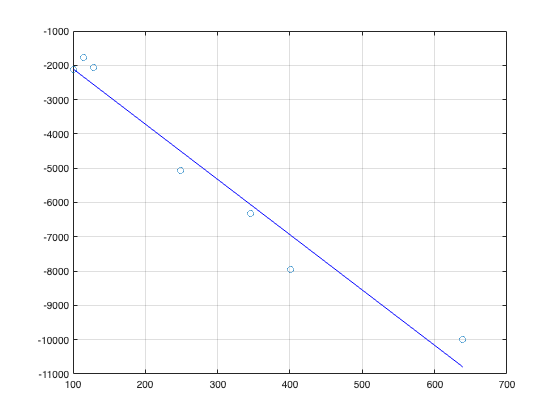

figure(20)
a2=polyfit(rcs,dati_approssimati,1);
retta=polyval(a2,griglia);
plot(rcs,dati_approssimati,'o',griglia,retta,'b')
grid on

**         3.3. Ripetere il punto precedente variando il grado del polinomio approssimante nell'intervallo tra 2 e 10. Mostrare tutte le curve approssimanti ottenute sullo stesso grafico.**

%Creazione griglia di 100 punti e ricostruzione del polinomio di secondo
%grado da approssimare e valuto l'approssimazione
xx2 = linspace(min(rcs), max(rcs), 100);

a3 = polyfit(rcs,dati_approssimati, 2);
parabola2 = polyval(a3, xx2);

a4 = polyfit(rcs,dati_approssimati, 3);
parabola3 = polyval(a4, xx2);

a5 = polyfit(rcs,dati_approssimati, 4);
parabola4 = polyval(a5, xx2);

a6 = polyfit(rcs,dati_approssimati, 5);

parabola5 = polyval(a6, xx2);

a7 = polyfit(rcs,dati_approssimati, 6);

parabola6 = polyval(a7, xx2);

a8 = polyfit(rcs,dati_approssimati,7);

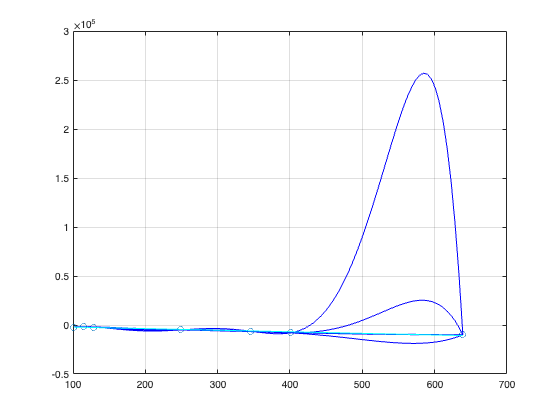

parabola7 = polyval(a8,xx2);

figure(21)
plot(rcs,dati_approssimati,'o',xx2,parabola2,'b') %visualizzo le parabole
hold on
grid on
plot(xx2,parabola3,'b')
plot(xx2,parabola4,'b')
plot(xx2,parabola5,'b')
plot(xx2,parabola6,'b')
plot(xx2,parabola7,'b')

plot(griglia,retta,'c')

**         3.4. Valutare il residuo in norma due per ognuna delle curve precedentemente ottenute.**

Vado a valutare ogni parabola con il vettore residuo della norma-2:

res_parabola = zeros(length(rcs), num_rcs); %mi calcolo il residuo della parabola
for i=1:7
    res_parabola(:, i) = abs(polyval(polyfit(rcs, dati_approssimati, i+1),rcs)-dati_approssimati)'; %qui vado a ciclare ogni parabola per calcolare i residui
end


for i=1:7
    norma2_res(i) = norm(res_parabola(i, :), 2); %calcolo la norma2
end

norma2_res %vado a visualizzarli 

norma2_res = 1.0e+02 *

   6.632726075942491   4.349191850836033   4.325105459280049   4.942505931616853   7.123889646024955   4.925103289518587   0.470368077273741


**4. Quadratura**

**    4.1. Definire un dominio **$[a,b]$** ed una funzione composta **$f(x)$** in MATLAB combinando  le principali funzioni elementari (polinomi, funzioni trigonometriche, logaritmi, esponenziali, etc etc). La funzione deve essere definita, positiva e continua in **$[a,b]$**. Usare la funzione **`ezplot`** per stabilire l'intervallo **$[a,b]$**; **

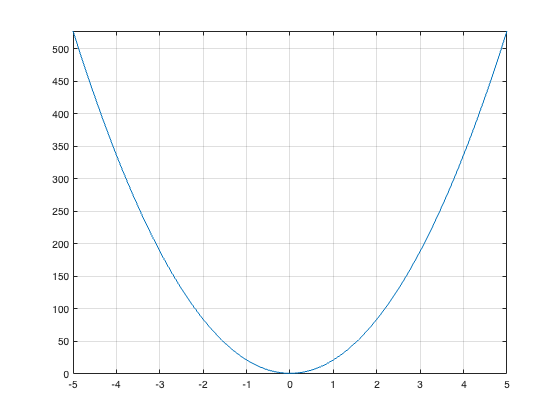

%creo funzione definita, positiva e continua in [a,b]
fun = @(x) exp(log(x.^2)+3)+cos(x)+x.^2; %creo la nuova funzione composta
figure(22)
fplot(fun)
grid on

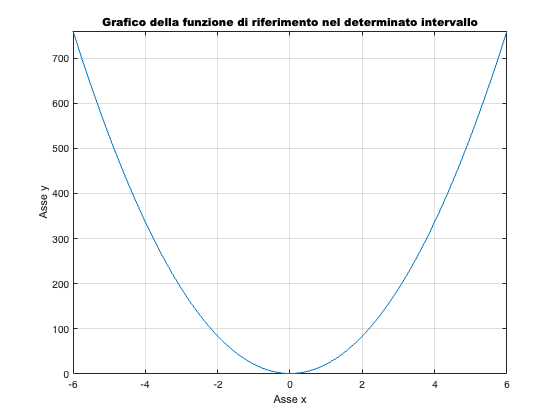

figure(23)
fplot(fun, [ar, br]) %stabilisco l'intevallo
hold on 
grid on 
xlabel("Asse x",'FontName','Arial') %do un nome all'asse x
ylabel("Asse y",'FontName','Arial') %do un nome all'asse y
title("Grafico della funzione di riferimento nel determinato intervallo",'FontName','Arial Black') %do un titolo al mio grafico
hold off

**    4.2. Considerare come valore esatto dell'integrale **$I=I[f]=\int_a^b f(x)dx$** il valore ottenuto mediante la funzione MATLAB **`integral`** con tolleranza **$10^{-9}$**;**

Vado a fare la funzione integranda:

Int = integral(fun,ar,br,'AbsTol',1e-9) %funzione integranda ottenuta utilizzando la funzione integral

Int =      3.035758485942626e+03


**    4.3. Stimare l'integrale **$I$** utilizzando le principali formule di quadratura (Rect. sx, Rect. dx, Punto medio, Trapez., Simpson) su **$1, 2,$** e **$3$** nodi e calcolare per ognuna di esse il corrispondente errore di discretizzazione.**

mr = (ar+br)/2;  %punto medio dell'intervallo
%formule per calcolare punto medio, trapezoidale e Simpson
    apprRSX = (br-ar)*fun(ar); 
    apprRDX = (br-ar)*fun(br);
    apprPMf = (br-ar)*fun(mr); 
    apprTf = (br-ar)/2*(fun(ar)+fun(br));
    apprSf = (br-ar)/6*(fun(ar)+4*fun(mr)+fun(br));

format long 

RSX = apprRSX'; 
RDX = apprRDX';
PMf = apprPMf'; 
TRf = apprTf'; 
SPf= apprSf'; 

Tabella1 = table(RSX,RDX,PMf,TRf,SPf) % generazione della tabella con risultati

Tabella1 = 1×5 table
          RSX                 RDX           PMf          TRf                 SPf       
    ________________    ________________    ___    ________________    ________________

    9120.47399425688    9120.47399425688    12     9120.47399425688    3048.15799808563


Calcolo gli errori di discretizzazione

%calcolo gli errori di discretizzazione
Err_RSX = abs(RSX-Int);
Err_RDX = abs(RDX-Int);
Err_PM = abs(PMf-Int);
Err_TR = abs(TRf-Int);
Err_SP = abs(SPf-Int); 
Tabella_Errori = table(Err_RSX,Err_RDX,Err_PM,Err_TR,Err_SP)

Tabella_Errori = 1×5 table
        Err_RSX             Err_RDX              Err_PM              Err_TR              Err_SP     
    ________________    ________________    ________________    ________________    ________________

    6084.71550831425    6084.71550831425    3023.75848594263    6084.71550831425    12.3995121429994


**4.4. Costruzione di formule di quadratura. Fissare **$p$ $3 \leq p \leq 5$** nodi distinti, non equispaziati, **$x_i \in [0,4]$**  di una formula di quadratura  **$Q[f]=w_1f(x_1)+w_2f(x_2)+\cdots+w_pf(x_p)$ **per il calcolo numerico dell'integrale definito della funzione **$f$** in **$[0,4]$**;**

p = 4; %nodi distinti
%intervallo
a3 = 0; b3 = 4;
%reimposto il nuovo punto medio dell'intervallo
m3 = (a3+b3)/2; 
%genero i nodi randomici ed equispaziati passando per nodi distinti
GQ = (b3-a3)*rand(p,1)+a3;
GQ = sort(GQ)

GQ =    0.708495017993266
   3.067686671741059
   3.318573542790338
   3.737913092473078


for i=1:p
    I_m(i,1) = ((b3^i-a3^i)/i)';
end

WP = [ones(size(GQ)) GQ GQ.^2 GQ.^3]' %creo la matrice sulla quadratura che mi servirà per calcolare i pesi

WP =    1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000
   0.708495017993266   3.067686671741059   3.318573542790338   3.737913092473078
   0.501965190521278   9.410701515977738  11.012930358908017  13.971994286881651
   0.355639836690366  28.869083612298290  36.547219317664648  52.226100372893981


**4.5.  Determinare i valori dei pesi **$w_i$** affinché la formula risulti esatta per polinomi algebrici di grado al più **$p-1$** (costruire e risolvere il sistema **$B^Tw=I$**.)**

w = WP\I_m %valore dei pesi

w =    1.703762970221508
   6.113028712522821
  -5.501201406587265
   1.684409723842937


QF = w(1)*fun(GQ(1))+w(2)*fun(GQ(2))+w(3)*fun(GQ(3))+w(4)*fun(GQ(4)) %utilizzo la formula per polinomi algebrici al grado p-1

QF =      4.490437627433968e+02


Allego come richiesto nel punto 2.4 la mia funzione 'perimetro' :

function miafun_perimetro = perimetro(xi,yi)

perimetro_poligono=sum(sqrt(diff(xi).^2 + diff(yi).^2)) %formula per calcolo del perimetro richiesto
  
end